clear;
clc;

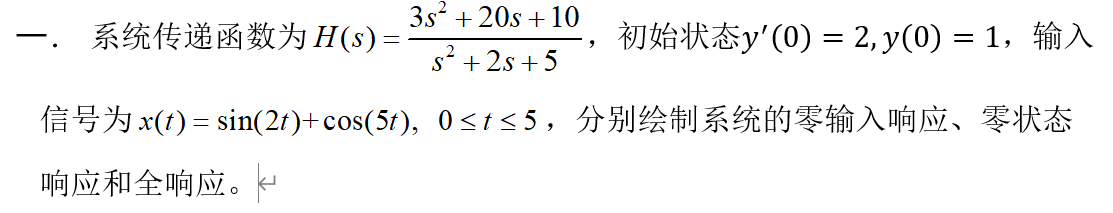

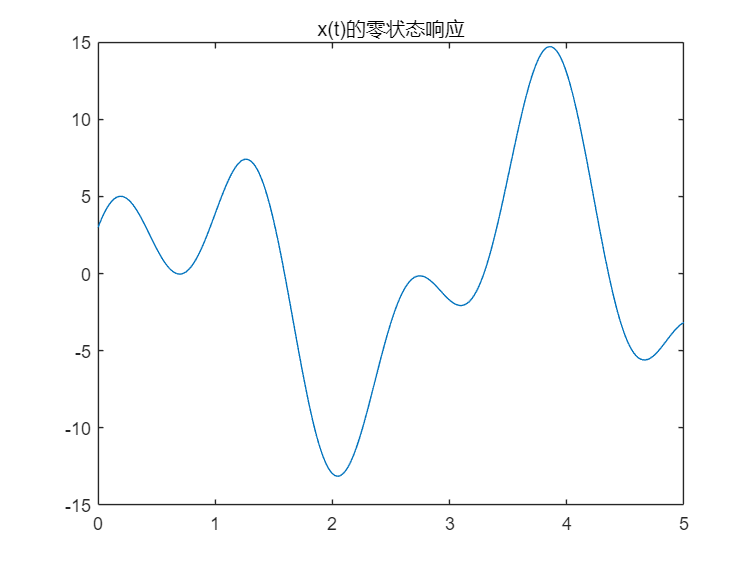

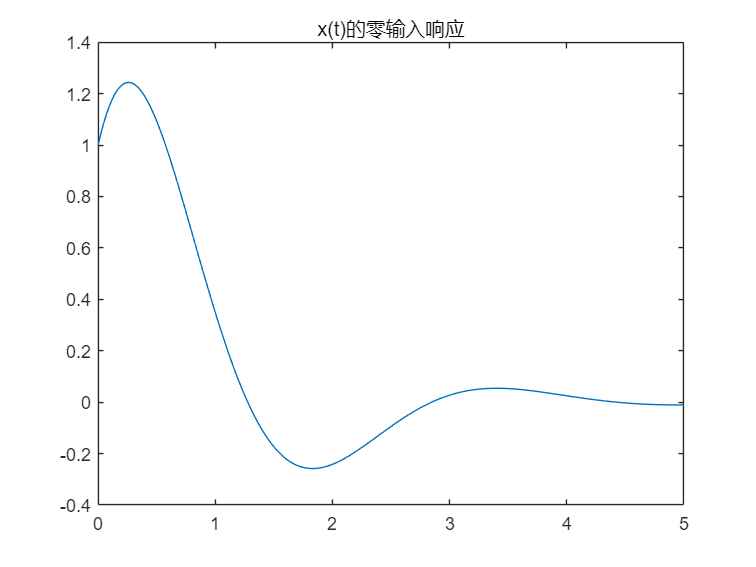

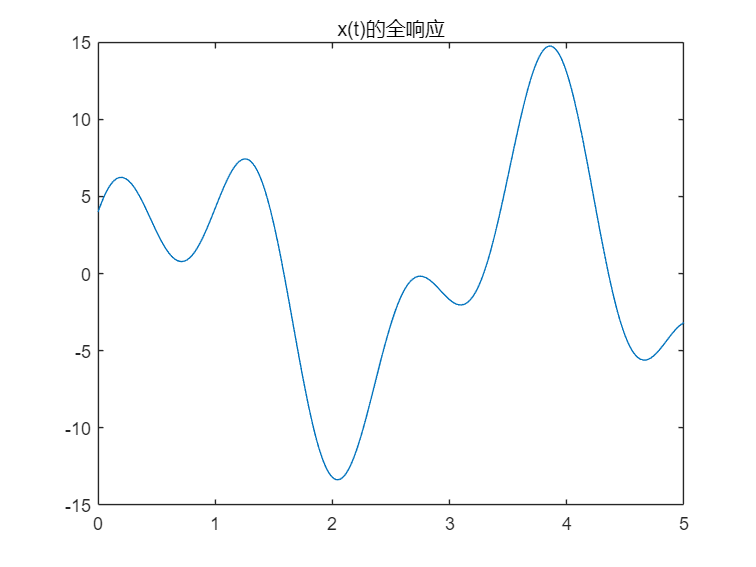

% 初始化系统参数
A = [3 20 10]; 
B = [1 2 5];   
t = 0:0.01:5;  % 定义时间向量
e = sin(2*t) + cos(5*t); % 定义输入信号

% 创建传递函数模型
sys = tf(A, B);  

% 计算并绘制零状态响应
y1 = lsim(sys, e, t);  
figure(1); 
plot(t, y1);  
title('x(t)的零状态响应');  

% 将传递函数模型转换为状态空间模型
[a, b, c, d] = tf2ss(A, B); 
sys0 = ss(a, b, c, d);  

% 定义状态空间模型的转换矩阵T和输入矩阵R
T = [1 -a(1, :); c 0; 0 c]; 
R = inv(T) * [0; 2; 1];  

% 计算并绘制零输入响应
y0 = initial(sys0, R(2:3), t);  % 使用initial函数计算零输入响应
figure(2);  
plot(t, y0); 
title('x(t)的零输入响应'); 

% 计算并绘制全响应
yy = y0 + y1;  
figure(3); 
plot(t, yy); 
title('x(t)的全响应');

clear;
clc;

#### 二．	求系统      的冲激和阶跃响应，以及激励为sin(t) (t>0)的零状态响应。

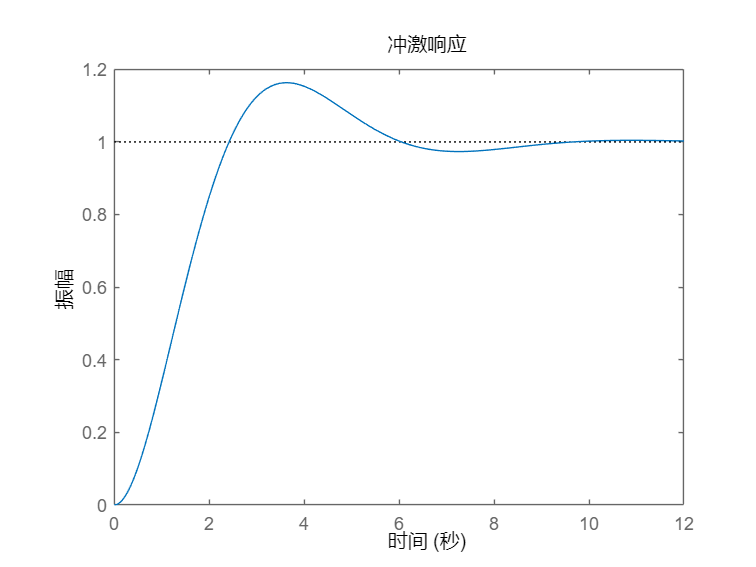

%系统与激励的描述
A=[0 0 0 1];
B=[1 1 1 0];
t=0:0.01:12;
e=sin(t);
sys=tf(A,B);
%冲激响应
figure(4);
impulse(sys,t);

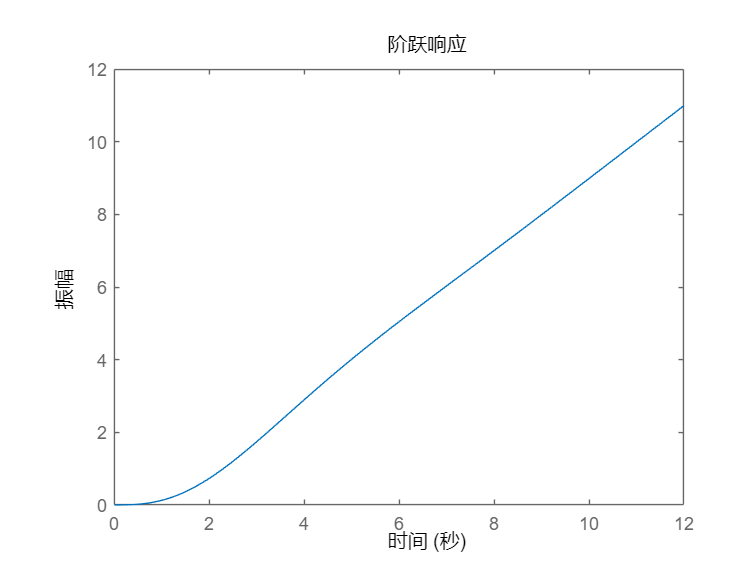

%阶跃响应
figure(5);
step(sys,t);

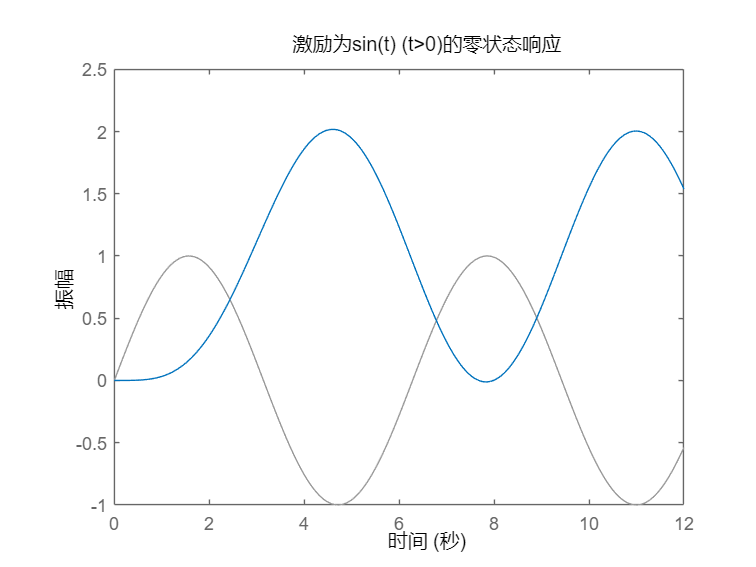

%外部激励的零状态响应
figure(6);
lsim(sys,e,t);
title('激励为sin(t) (t>0)的零状态响应');

clear;
clc;

#### 三．	用MATLAB提供的库函数求零状态响应

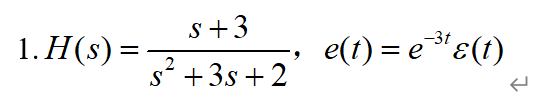

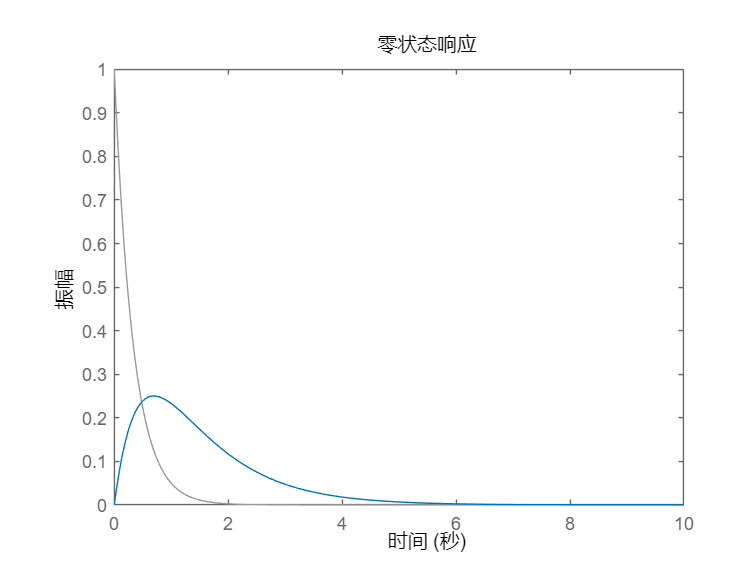

%系统与激励的描述
A31=[0 1 3];
B31=[1 3 2];
sys31=tf(A31,B31);
t=0:0.01:10;
e31=exp(-3*t);
%外部激励的零状态响应
figure(7);
lsim(sys31,e31,t);
title('零状态响应');

clear;
clc;

#### 四．	用MATLAB求下列齐次差分方程描述的系统的单位脉冲响应，以及激励为 的响应：

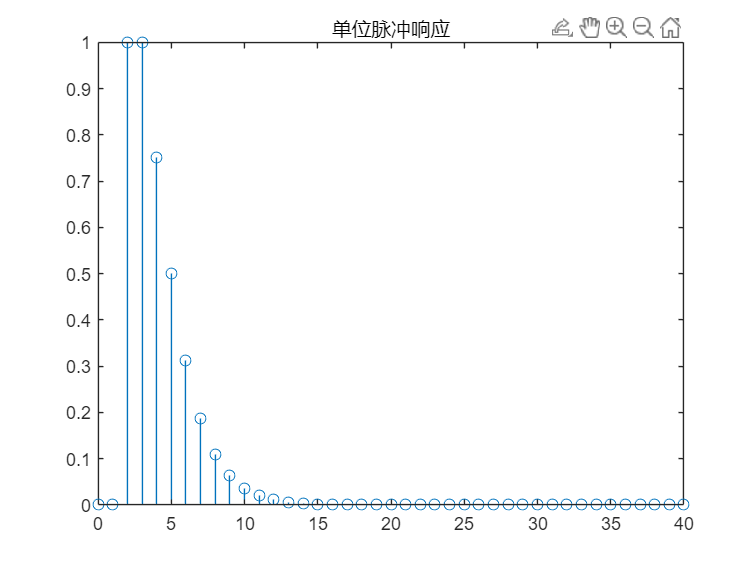

n=0:1:40;
%单位脉冲响应
A=[1];
B=[1 -1 0.25];
x=[1 zeros(1,40)];
y1=dimpulse(A,B,41);
figure(8);
stem(n,y1);
title('单位脉冲响应');

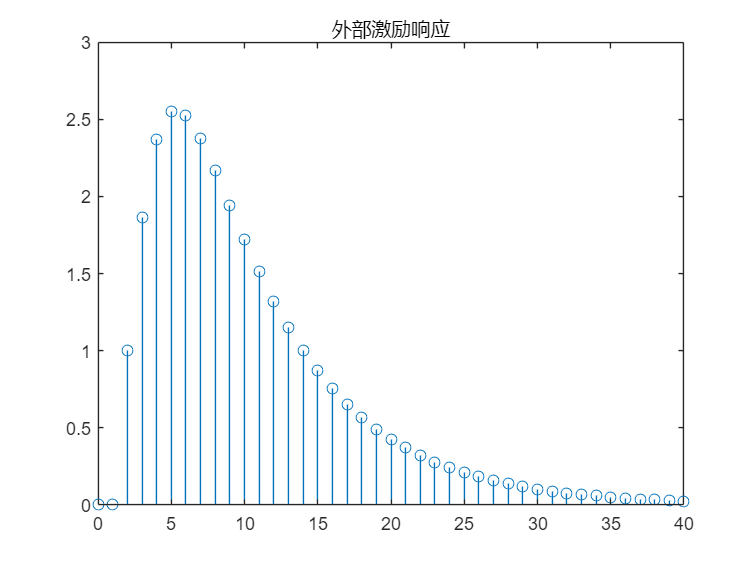

%外部激励响应
e0=exp(-n./7);
A0=[0 0 1];
B0=[1 -1 0.25];
y2=filter(A0,B0,e0);
figure(9);
stem(n,y2);
title('外部激励响应');

clear;
clc;

#### 五．	离散系统结构如图所示：

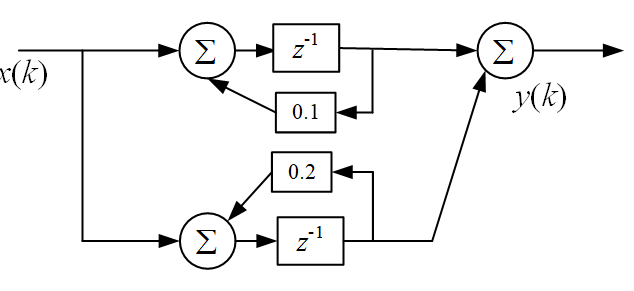

#### 首先分析系统的稳定性，并且绘制出系统在激励信号为x(k)=2$\delta$k)时的响应，给出该响应的前8个输出值。

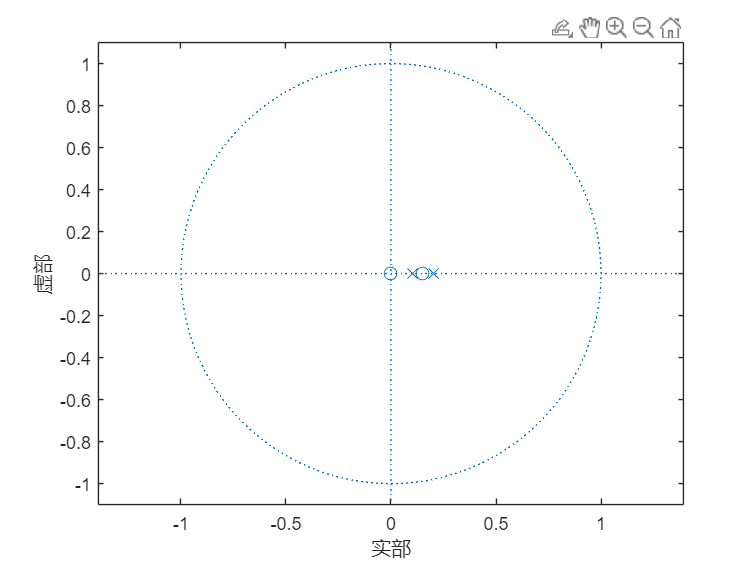

%判断稳定性
num=[2 -0.3];%分子
den=[1 -0.3 0.02];%分母
[z ,p ,k]=tf2zpk(num,den);
%画极零图判断稳定性
figure(10);
zplane(z,p);

系统的稳定性判断：极点均在单位圆内，故而系统是稳定的。

%求响应
x = [2 zeros(1, 7)];%激励
k = 0:7;% 定义时间范围
y = filter(num, den, x);%计算响应
yy=2*dimpulse(num,den,8);
disp('前8个输出值:');

前8个输出值:


disp(yy);%显示前8个输出值

         0
    4.0000
    0.6000
    0.1000
    0.0180
    0.0034
    0.0007
    0.0001



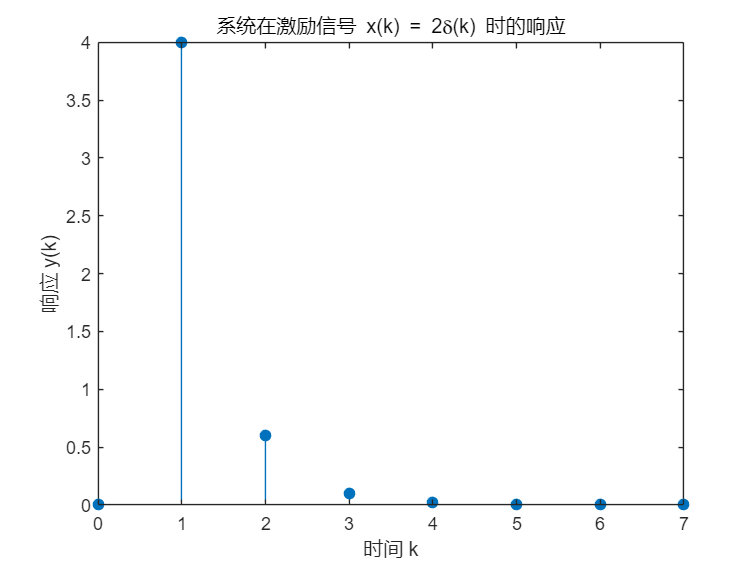

figure(12);
stem(k, yy, 'filled');
xlabel('时间 k');
ylabel('响应 y(k)');
title('系统在激励信号 x(k) = 2\delta(k) 时的响应');